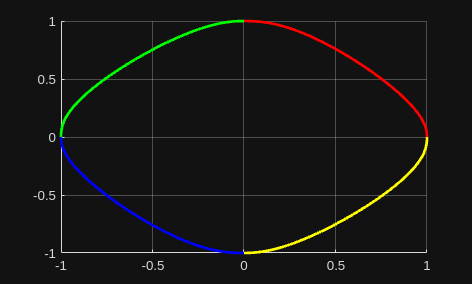

px = [1 0 -1 0]; %cos
py = [0 1 0 -1]; %sin
pz = [0 1 2 3]; %sin
p = [px;py;pz];

dpx = [0 -1 0 1]; %-sin
dpy = [1 0 -1 0]; %cos
dpz = [1 1 1 -1]; %cos
dp = [dpx;dpy;dpz];

ddpx = [-1 0 1 0]; %-cos
ddpy = [0 -1 0 1]; %-sin
ddpz = [-1 0 0 -1]; %-sin
ddp = [ddpx;ddpy;ddpz];

f = PathPlanning(p,dp,ddp);
N = size(p,2);
n = size(p,1);

s = 0:0.01:1;
f_ = zeros(1,size(p,2),length(s));
for j = 1:n
    g = f{j};
    for i = 1:length(s)
        f_(j,:,i) = g(s(i));
    end
end



x1 = f_(1,1,:);
y1 = f_(2,1,:);
z1 = f_(3,1,:);

x2 = f_(1,2,:);
y2 = f_(2,2,:);
z2 = f_(3,2,:);

x3 = f_(1,3,:);
y3 = f_(2,3,:);
z3 = f_(3,3,:);

x4 = f_(1,4,:);
y4 = f_(2,4,:);
z4 = f_(3,4,:);
hold on
plot3(x1(:),y1(:),z1(:),'Color','r','LineWidth', 2)
plot3(x2(:),y2(:),z2(:),'Color','g','LineWidth', 2)
plot3(x3(:),y3(:),z3(:),'Color','b','LineWidth', 2)
plot3(x4(:),y4(:),z4(:),'Color','y','LineWidth', 2)
grid on